# Exam January 11, 2018

## Exercise 1

% % %Panda robot
%  clear ; close all;% clc;
% % q = sym('q',[1 7])
% % al = pi/2; % rotation 
% % %a = 3
% % d = 10
% % syms a d 
% % dh = [al 0 d q(1);
% %       -al 0 0 q(2);
% %       al a d q(3);
% % %       -al -a 0 q(4);
% % %       al 0 d q(5);
% % %       al a 0 q(6);
% % %         0 0 d q(7);
% %                     ]
% % 
% % % [T1 Tpartial] = getTranslationMatrix(dh,'alpha')
% % % [T2 Tpartial2] = getTranslationMatrix(dh.*[-ones(7,1) ones(7,3)],'alpha')
% % % dh = subs(dh,[a d],[10 100])    
% % %dh = subs(dh,[a d],[10 100])
% % 

% % % T1-T2
% %  NJoints=7
% % % 
% %  q = sym('q',[NJoints 1],'real')
% %  q_d1 = sym('q_d1',[NJoints 1],'real')
% % 
% %  d = sym('d',[NJoints 1],'real')
% %  alpha = sym('alpha',[NJoints 1],'real')
% %  a = sym('a',[NJoints 1],'real')
% %  d_=100
% %  a_=30
% %  al=pi/2;
% %  d_=10*[1,0,1,0,1,0,1]'
% %  a_=03*[0,0,1,1,0,1,0]'
% %  dh = [ al  0       d(1)    q(1);
% %        -al  0       0       q(2);
% %         al  a(3)    d(3)    q(3);
% %        -al  -a(4)    0       q(4);
% %         al  0       d(5)    q(5);
% %         al  a(6)    0       q(6);
% %         0   0       d(7)    q(7);
% %         ]
% % 
% % % dh_=subs(dh,[a(:);d(:)],[a_(:);d_(:)])
% % % 
% % % links = getDHforTB(dh_,'alpha');
% % 
% % 
% % % c600 = SerialLink(links);
% % % c600.teach([0,0,0,-pi/2,0,0,0],'view','x'  )
% % 
% % % dht = getDHforTB(dh,'alpha')
% % % 
% % % r = SerialLink(dht)
% % % r.teach

## Computing total number of computations

% % 
% % [T_total T_Partial,RTotal,RPartial,PTotal, PPartial] = getTransformationMatrix(dh,'alpha',false);
% % % PTotal
% % T_Partial{7}
% % 
% %  phomvector=[ zeros(3,1);1] ;
% % n_p=[];
% % for inm=[NJoints:-1:1]
% %     
% %     phomvector=simplify(T_Partial{inm}*phomvector);%optimal way to compute the P vector, uncoment this
% %     temp1=find(phomvector~=0&phomvector~=1);
% %     totaloperations=sym('totaloperations_'+string(inm)+'_',[size(temp1,1),1],'real');
% %     phomvector=subs(phomvector,phomvector(temp1),totaloperations)
% %     n_p=phomvector;
% % end
% % % [JL, JA,JLs, JAs] = getJacobian(dhsym_, sigma, 'alpha');
% % % JL1=RPartial{1}'*JL
% 

## Exercise 3

% sigma='RRR'; 
% NJoints=3;
% % 
%  q = sym('q',[NJoints 1],'real')
%  qS = sym('qS',[NJoints 1],'real')
% 
%  q_0=[pi/2,-pi/3,0]';
%  qM_d1_0=[-pi/6,0,-pi/2]';
%  qM_d1 = sym('qM_d1',[NJoints 1],'real')
%  qS_d1 = sym('qS_d1',[NJoints 1],'real')
%  alphaMS = sym('alphaMS',[1 1],'real');
% alphaMS_=pi;
%  d = sym('d',[NJoints 1],'real')
%  alpha = sym('alpha',[NJoints 1],'real')
%  a = sym('a',[NJoints 1],'real')
%  L = sym('L',[NJoints 1],'real')
%  L_=[0.5,0.5,0.25]';
% a=L_
%  a_=L_;
%  dh = [ 0  a(1)     0    q(1);
%         0  a(2)     0    q(2);
%         0  a(3)     0    q(3);
% 
%         ]
% 
% % dh_=subs(dh,[a(:);d(:)],[a_(:);d_(:)])
% 
% links = getDHforTB(dh,'alpha');
% 
% 
% % c600 = SerialLink(links);
% % c600.teach([27.4,-76.6,93.1]*pi/180,'view','top'  )
% 
% [T_total T_Partial,RTotal,RPartial,PTotal, PPartial] = getTransformationMatrix(dh,'alpha',false);
% [JLM, JAM,JLMs, JAMs] = getJacobian(dh, sigma, 'alpha');
% R_MS=getEulerRotMatProduct('Z',alphaMS)
% R_SM=R_MS';
% R_SM_=vpa(subs(R_SM,alphaMS,alphaMS_))
% 
% P_MS=[1.6,0.9,0]';
% T_MS=[R_MS,P_MS;[0,0,0,1]];
% T_Ms_=vpa(subs(T_MS,alphaMS,alphaMS_))

## master robot computations

% %Values to eval
% M_Values=[L;q];
% M_Values_=[L_;q_0];
% %%
% PM_=vpa(subs(PTotal,M_Values,M_Values_))
% JLM_=vpa(subs(JLM,M_Values,M_Values_))
% 
% PM_=[PM_;1];
% PS_=T_Ms_*PM_
% vM=JLM*qM_d1;
% VS_=R_SM_*vM;
% VS_=vpa(subs(VS_,[q,qM_d1],[q_0,qM_d1_0]))
% VS=subs(vM,[L,q,qM_d1],[L_,qS,qS_d1])
% PS=subs(PTotal,[L;q],[L_;qS])
% 
% 

## my aproach funciona medio medio ajajaj por si no queda tiempo de usar lo de luca

% 
% 
% % digits(6)
% % PS3=subs(PPartial{3},[L;q],[L_;qS])
% % PS=subs(PTotal,[L;q],[L_;qS])
% % 
% % sol1=solve(simplify([dot(PS3(1:2),PS(1:2))==0;PS_(1:2)==PS(1:2)]))%% only this worked for me, check later if we have time
% % [Vdvarray_,Vdvnames_,vartosolve]=solvetoarray(sol1,qS)
% % % figure(2)
% % close all
% % c6001 = SerialLink(links);
% % c6001.teach(eval(vartosolve(:,3)'),'view','top'  )
% 
% 
% 

## luca aproach

% thetas=vpa(atan2(VS_(2),VS_(1))-pi/2);%-pi/2 desfase%
% PS_theta_s=subs(PS,sum(qS),thetas)
% eqn3=[PS_(1:2)==PS_theta_s(1:2);(vpa(atan2(VS_(2),VS_(1))-pi/2)==sum(qS))]
% solluca=solve(eqn3)
% [Vdvarray_,Vdvnames_,vartosolve]=solvetoarray(solluca,qS)
% % figure(2)
% close all
% c6001 = SerialLink(links);
% c6001.teach(eval(vartosolve(:,2)'),'view','top'  )
% qS_0=vartosolve(:,2);

## computing qS_d1 derivadas para los que no saben xD

% rS=[PS(1:2);sum(qS)]
% JrSL=jacobian(rS,qS)
% rS_d1=[VS(1:2);0] % the last term is always cero because qS1 + qS2 + qS3=0 
% qS_d1_=inv(JrSL)*[VS_(1:2);0];
% qS_d1_=subs(qS_d1_,[qS],[qS_0])

## In degrees

% vpa(qS_d1_*180/pi)% igual que al profe



## Exercise 4

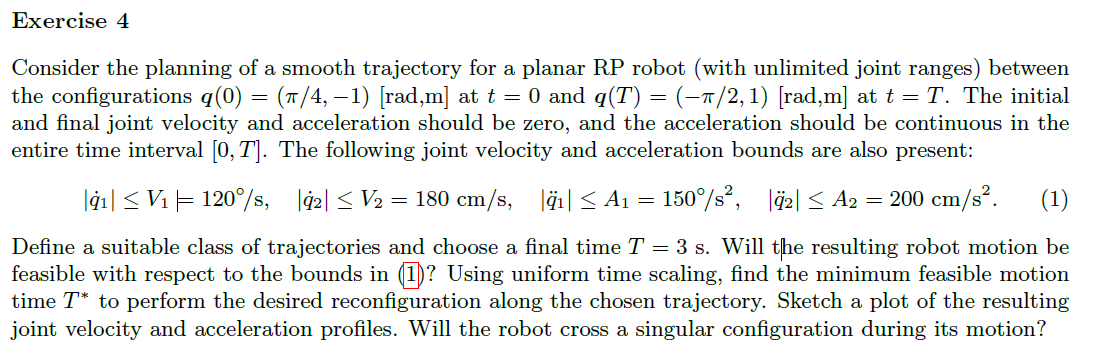

## arci aproach


% q_0 = sym('q_0',[2,1])
% q_delta = sym('q_delta',[2,1])
% tau =sym('tau',[2,1])
% 
% q_0_val = [pi/4;-1];
% q_delta_val = [-pi/2-pi/4; 1-(-1)] 
% q_tau = q_0 + q_delta*(6*tau^5 -15*tau^4 + 10*tau^3 )

% qd_tau = diff(q_tau)
% qdd_tau = diff(qd_tau)
% qddd_tau = diff(qdd_tau)

% tau_a_max = solve(qddd_tau == [0;0])

% % a_max = eval(subs( qdd_tau , tau , tau_a_max)) %test it

% 10*sqrt(3)/3

% q = sym('q',[1,2])
% dhTable = [-pi/2,0,0,q(1);
%            pi/2,0,q(2),0];
% T = getTransformationMatrix(dhTable,'alpha')

% q_tau_subs = subs(q_tau,[q_0, q_delta],[q_0_val, q_delta_val])
% qd_tau_subs = subs(qd_tau,[q_0, q_delta],[q_0_val, q_delta_val])

% fplot(q_tau_subs.*[180/pi; 100],[0,1])
% fplot(qd_tau_subs.*[180/pi; 100],[0,1]) % 


## David aproach

clear;
t_=sym('t_','real');%don't change it or it wont work
N=2;
M=N-1;
NumJoints=1;% no modificar no funciona para 2
t_values=[ 0, 2.4028114141347542810268440585917];%[0,3];
q_values(1,:)=[pi/4,-pi/2]*180/pi;
q_values2(1,:)=[-100,100];
polg=5;

[spline_fun,Aw_fun,Aa_fun,Ajerk_fun,MaxsVal] = splinesD(N,NumJoints,t_values,q_values,polg)

NumJoints = 1

M = 1

v_init = 0

a_init = 0

v_end = 0

a_end = 0

ak = struct with fields:
    ak_1: [1×1 sym]
    ak_2: [1×1 sym]
    ak_3: [1×1 sym]
    ak_4: [1×1 sym]
    ak_5: [1×1 sym]


ans = 1×5 string array
    "0"    "0"    "10*q2 - 10*q1"    "15*q1 - 15*q2"    "6*q2 - 6*q1"


$$spline\_fun = -\frac{46895796141113059146546248928518602680574343789584428435980321523204817504174080\,{\mathrm{t\_}}^{5}}{4637109228098889973450347477860754148606051006030059333473789813109634916175907}+\frac{52064792633991284927559571791853668321719376998562487863764582400\,{\mathrm{t\_}}^{4}}{857033623604794837236150617194974373516417636007374241262372241}-\frac{15414275081224366715429488470054547472933663539200\,{\mathrm{t\_}}^{3}}{158397526531911407291271661614100291896831157483}+45$$

$$spline\_fun = -\frac{46895796141113059146546248928518602680574343789584428435980321523204817504174080\,{\mathrm{t\_}}^{5}}{4637109228098889973450347477860754148606051006030059333473789813109634916175907}+\frac{52064792633991284927559571791853668321719376998562487863764582400\,{\mathrm{t\_}}^{4}}{857033623604794837236150617194974373516417636007374241262372241}-\frac{15414275081224366715429488470054547472933663539200\,{\mathrm{t\_}}^{3}}{158397526531911407291271661614100291896831157483}+45$$

$$Aw\_fun = -\frac{234478980705565295732731244642593013402871718947922142179901607616024087520870400\,{\mathrm{t\_}}^{4}}{4637109228098889973450347477860754148606051006030059333473789813109634916175907}+\frac{208259170535965139710238287167414673286877507994249951455058329600\,{\mathrm{t\_}}^{3}}{857033623604794837236150617194974373516417636007374241262372241}-\frac{46242825243673100146288465410163642418800990617600\,{\mathrm{t\_}}^{2}}{158397526531911407291271661614100291896831157483}$$

$$Aa\_fun = -\frac{937915922822261182930924978570372053611486875791688568719606430464096350083481600\,{\mathrm{t\_}}^{3}}{4637109228098889973450347477860754148606051006030059333473789813109634916175907}+\frac{624777511607895419130714861502244019860632523982749854365174988800\,{\mathrm{t\_}}^{2}}{857033623604794837236150617194974373516417636007374241262372241}-\frac{92485650487346200292576930820327284837601981235200\,\mathrm{t\_}}{158397526531911407291271661614100291896831157483}$$

$$Ajerk\_fun = -\frac{2813747768466783548792774935711116160834460627375065706158819291392289050250444800\,{\mathrm{t\_}}^{2}}{4637109228098889973450347477860754148606051006030059333473789813109634916175907}+\frac{1249555023215790838261429723004488039721265047965499708730349977600\,\mathrm{t\_}}{857033623604794837236150617194974373516417636007374241262372241}-\frac{92485650487346200292576930820327284837601981235200}{158397526531911407291271661614100291896831157483}$$

MaxsVal = struct with fields:
     timepeak: [1×1 struct]
    PeakValue: [1×1 struct]


[spline_fun2,Aw_fun2,Aa_fun2,Ajerk_fun2,MaxsVal2] = splinesD(N,NumJoints,t_values,q_values2,polg)

### Get splines plots

% Angles
figure
for i = 1:M
    fplot(spline_fun(i,:),t_values(i:i+1)) 
    hold on
     fplot(spline_fun2(i,:),t_values(i:i+1)) 
    hold on
end

% Angular velocity
figure
for i = 1:M
%     fplot(diff(spline_fun(i),t_),t_values(i:i+1))
    fplot(Aw_fun(i,:),t_values(i:i+1))

    hold on
      fplot(Aw_fun2(i,:),t_values(i:i+1)) 
     hold on

end

% Angular acceleration
figure
for i = 1:M
%     fplot(diff(diff(spline_fun(i),t_)),t_values(i:i+1))
    fplot(Aa_fun(i,:),t_values(i:i+1))
    hold on
      fplot(Aa_fun2(i,:),t_values(i:i+1))
    hold on
end


## finding maxs velocities

%% k for vmax
 % q1
vmax=120
MaxsVal.PeakValue.Aw
[K_w_q1,indkw1]=max(abs(MaxsVal.PeakValue.Aw/vmax))
tv_values_scaled1=t_values(1)+(t_values-t_values(1))*K_w_q1

 % q2
vmax=180
MaxsVal.PeakValue.Aw
[K_w_q2,indkw1]=max(abs(MaxsVal2.PeakValue.Aw/vmax))
tv_values_scaled2=t_values(1)+(t_values-t_values(1))*K_w_q2

%% k for amax
% q1
amax=150
MaxsVal.PeakValue.Aa
[K_a_q1,indka2]=max(sqrt(abs(MaxsVal.PeakValue.Aa/amax)))
ta_values_scaled2=t_values(1)+(t_values-t_values(1))*K_a_q1

% q2
amax=200
MaxsVal.PeakValue.Aa
[K_a_q2,indka2]=max(sqrt(abs(MaxsVal2.PeakValue.Aa/amax)))
ta_values_scaled2=t_values(1)+(t_values-t_values(1))*K_a_q2


## new k for speed up motion minumum motion time

[k_q1,indk1]=max([ K_w_q1,K_a_q1])
t1_values_scaled=t_values(1)+(t_values-t_values(1))*k_q1

[k_q2,indk1]=max([ K_w_q2,K_a_q2])
t2_values_scaled=t_values(1)+(t_values-t_values(1))*k_q2
